# Data Import and Processing

In MATLAB import external data in two ways,

- Manual Data Import

- Automatic Data Import

clearvars

## Step-1: Manual Data Import

Data=readtable("Diabetes Missing Data.csv")

Data = 768×9 table
    Pregnant    Glucose    Diastolic_BP    Skin_Fold    Serum_Insulin    BMI     Diabetes_Pedigree    Age    Class
    ________    _______    ____________    _________    _____________    ____    _________________    ___    _____

        6         148           72             35            NaN         33.6          0.627          50       1  
        1          85           66             29            NaN         26.6          0.351          31       0  
        8         183           64            NaN            NaN         23.3          0.672          32       1  
        1          89           66             23             94         28.1          0.167       

Data.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Pregnant'  'Glucose'  'Diastolic_BP'  'Skin_Fold'  'Serum_Insulin'  'BMI'  'Diabetes_Pedigree'  'Age'  'Class'}
           VariableTypes: ["double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"]
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


## Step-2: Automatic Data Import

% Import data from text file
DiabetesMissingData = readtable("Diabetes Missing Data.csv");

% Display results
DiabetesMissingData

DiabetesMissingData = 768×9 table
    Pregnant    Glucose    Diastolic_BP    Skin_Fold    Serum_Insulin    BMI     Diabetes_Pedigree    Age    Class
    ________    _______    ____________    _________    _____________    ____    _________________    ___    _____

        6         148           72             35            NaN         33.6          0.627          50       1  
        1          85           66             29            NaN         26.6          0.351          31       0  
        8         183           64            NaN            NaN         23.3          0.672          32       1  
        1          89           66             23             94         28.1       

## Step-3: Investigate Missing Data Information

missing_data_matrix=ismissing(DiabetesMissingData);
Columnwise_Missing_Data_Info=sum(missing_data_matrix)

Columnwise_Missing_Data_Info =      0     5    35   227   374    11     0     0     0


Total_Missing_Data=nnz(missing_data_matrix)

Total_Missing_Data = 652

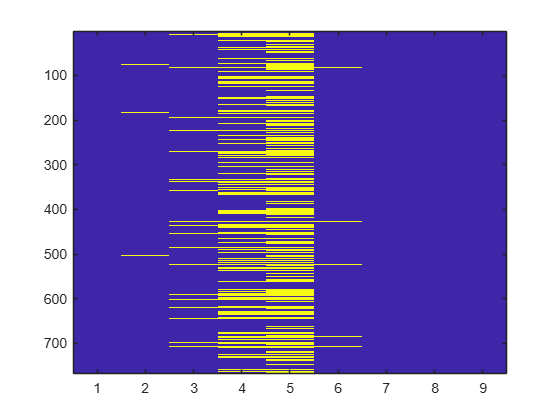

imagesc(missing_data_matrix)

## Step-4: Handling the Missing Data

avg_GLUCOSE=round(mean(DiabetesMissingData.Glucose,"omitmissing"))

avg_GLUCOSE = 122

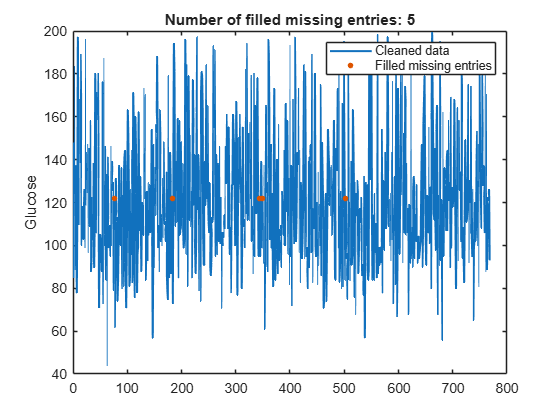

% Fill missing data
[newTable,missingIndices] = fillmissing(DiabetesMissingData,"constant",avg_GLUCOSE, ...
    DataVariables="Glucose");

% Display results
figure

% Plot cleaned data
plot(newTable.Glucose,SeriesIndex=1,LineWidth=1.5,DisplayName="Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices(:,2)),newTable.Glucose(missingIndices(:,2)),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,2)))

hold off
legend
ylabel("Glucose")

clear missingIndices

avg_DIA_BP=round(mean(DiabetesMissingData.Diastolic_BP,"omitmissing"))

avg_DIA_BP = 72

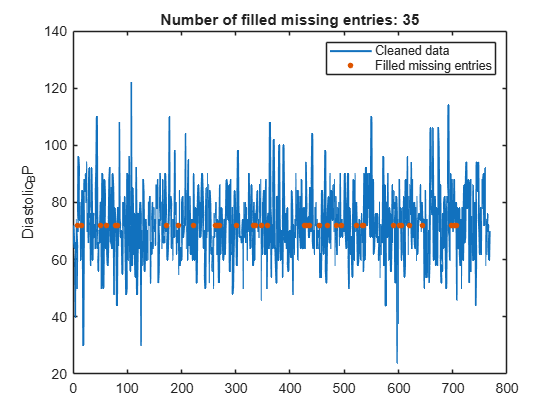

% Fill missing data
[newTable,missingIndices] = fillmissing(newTable,"constant",avg_DIA_BP, ...
    DataVariables="Diastolic_BP");

% Display results
figure

% Plot cleaned data
plot(newTable.Diastolic_BP,SeriesIndex=1,LineWidth=1.5,DisplayName="Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices(:,3)),newTable.Diastolic_BP(missingIndices(:,3)),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,3)))

hold off
legend
ylabel("Diastolic_BP")

clear missingIndices

avg_SKIN_FOLD=round(mean(DiabetesMissingData.Skin_Fold,"omitmissing"))

avg_SKIN_FOLD = 29

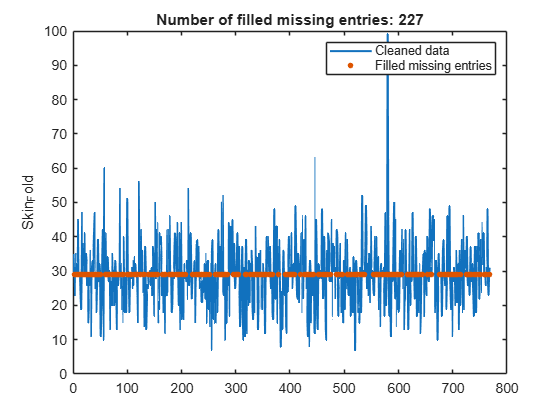

% Fill missing data
[newTable,missingIndices] = fillmissing(newTable,"constant",avg_SKIN_FOLD, ...
    DataVariables="Skin_Fold");

% Display results
figure

% Plot cleaned data
plot(newTable.Skin_Fold,SeriesIndex=1,LineWidth=1.5,DisplayName="Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices(:,4)),newTable.Skin_Fold(missingIndices(:,4)),".",...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,4)))

hold off
legend
ylabel("Skin_Fold")

clear missingIndices

avg_SERUM_INSULIN=round(mean(DiabetesMissingData.Serum_Insulin,"omitmissing"))

avg_SERUM_INSULIN = 156

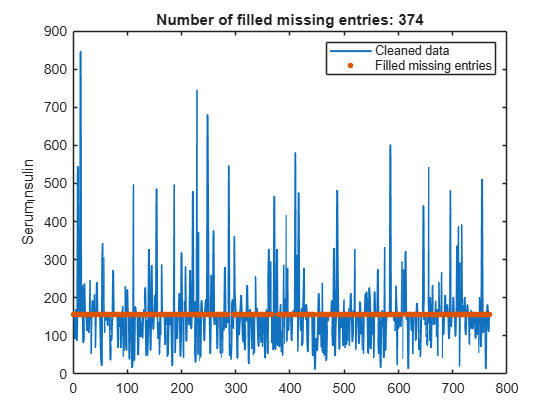

% Fill missing data
[newTable,missingIndices] = fillmissing(newTable,"constant",avg_SERUM_INSULIN, ...
    DataVariables="Serum_Insulin");

% Display results
figure

% Plot cleaned data
plot(newTable.Serum_Insulin,SeriesIndex=1,LineWidth=1.5,DisplayName="Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices(:,5)),newTable.Serum_Insulin(missingIndices(:,5)),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,5)))

hold off
legend
ylabel("Serum_Insulin")

clear missingIndices

avg_BMI=mean(DiabetesMissingData.BMI,"omitmissing")

avg_BMI = 32.4575

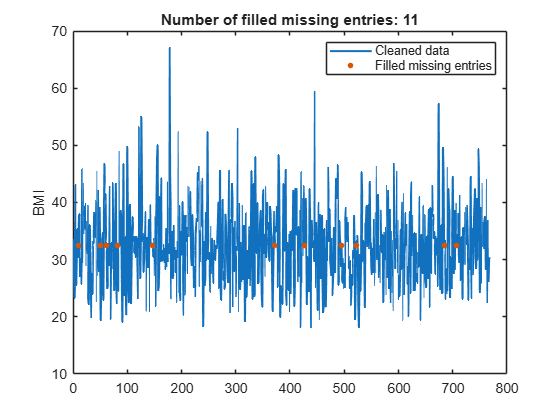

% Fill missing data
[newTable,missingIndices] = fillmissing(newTable,"constant",avg_BMI, ...
    DataVariables="BMI");

% Display results
figure

% Plot cleaned data
plot(newTable.BMI,SeriesIndex=1,LineWidth=1.5,DisplayName="Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices(:,6)),newTable.BMI(missingIndices(:,6)),".", ...
    MarkerSize=12,SeriesIndex=2,DisplayName="Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices(:,6)))

hold off
legend
ylabel("BMI")

clear missingIndices

## Verification of Data Processing

missing_data_matrix_PR=ismissing(newTable);
Columnwise_Missing_Data_Info_PR=sum(missing_data_matrix_PR)

Columnwise_Missing_Data_Info_PR =      0     0     0     0     0     0     0     0     0


Total_Missing_Data_PR=nnz(missing_data_matrix_PR)

Total_Missing_Data_PR = 0

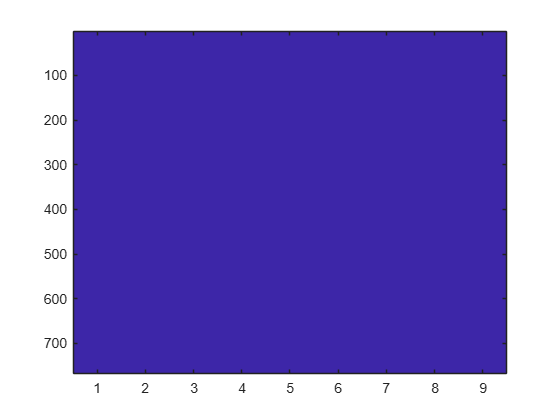

imagesc(missing_data_matrix_PR)

## Data Export

writetable(newTable,"Processed_Data.csv")
writetable(newTable,"Processed_Data.xlsx")